close all;
clear variables;

spectra = importdata ("spectra.csv");
starNames = importdata ("star_names.csv");
lambdaStart = importdata ("lambda_start.csv");
lambdaDelta = importdata ("lambda_delta.csv");

lambdaPr = 656.28; % нм
speedOfLight = 299792.458; % км/c

plotColors = [0.5 0.2 0.2;
              0.1 0.5 0.8;
              0.2 0.7 0.6;
              0.8 0.7 0.3;
              0.9 1.0 0.0;
              0.5 0.3 0.5;
              0.7 0.8 0.2];

nObs = size (spectra, 1);
nStars = size (spectra, 2);

lambdaEnd = lambdaStart + (nObs - 1) * lambdaDelta;
lambda = (lambdaStart : lambdaDelta : lambdaEnd)';

[sHa, idx] = min (spectra);
lambdaHa = lambda (idx);
speed = ((lambdaHa ./ lambdaPr) - 1) * speedOfLight;
movaway = starNames(speed > 0)

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}


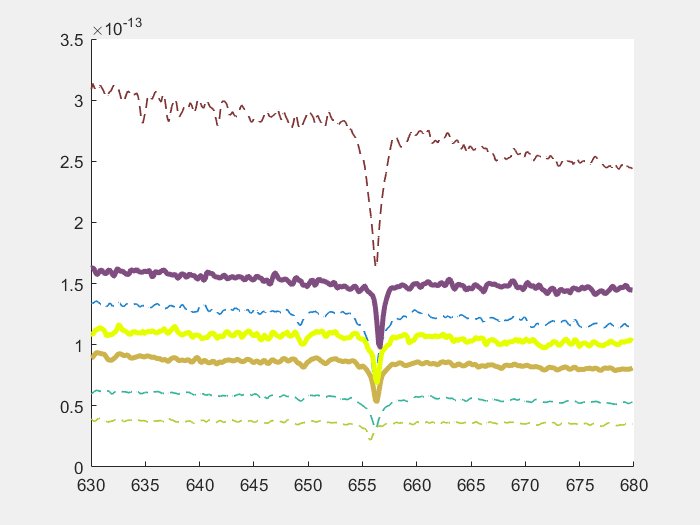

fg = figure;
set (fg, 'Visible', 'on');
hold on;
for i = 1 : nStars
    if (speed (i) < 0)
        plot (lambda, spectra (:, i), '--', 'Color', plotColors (i, :), 'LineWidth', 1);
    else
        plot (lambda, spectra (:, i), '-', 'Color', plotColors (i, :), 'LineWidth', 3);
    end
end

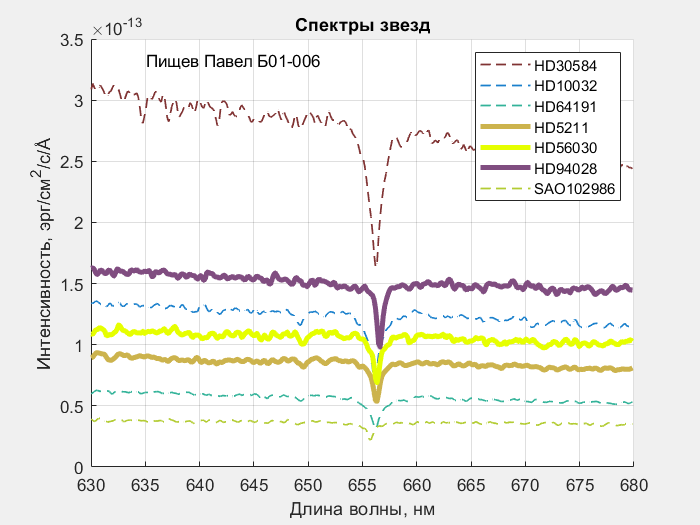

grid on;
xlabel ('Длина волны, нм');
ylabel (['Интенсивность, эрг/см^2/c/', char (197)]);
title ('Спектры звезд');
ax = gca;
text (lambdaStart + 5, 0.95 * max(ax.YLim) , 'Пищев Павел Б01-006');
legend (starNames);
hold off;

saveas (fg, "spectra.png");